clearvars

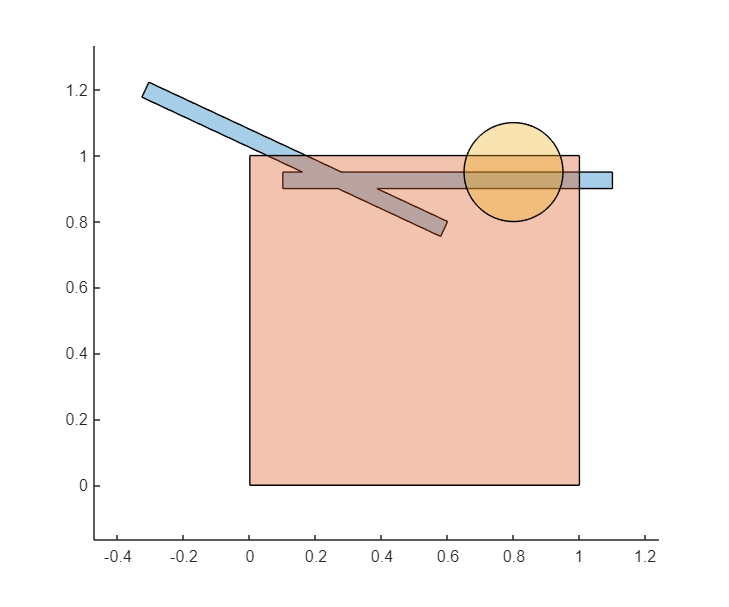

vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);

psRodBase = scale( psUnitSq, [1, 0.05]);
psRodA = rotate( psRodBase, 155 );
psRodA = translate( psRodA, [0.6 0.8] );
psRodB = translate( psRodBase, [0.1 0.9] );
psRodAB = union( psRodA, psRodB );

t = 0.05:0.03:2*pi;
x1 = 0.8 + 0.15*cos(t);
y1 = 0.95 + 0.15*sin(t);
psCircle = polyshape(x1,y1);

plot([ psRodAB; psUnitSq; psCircle ]); axis equal

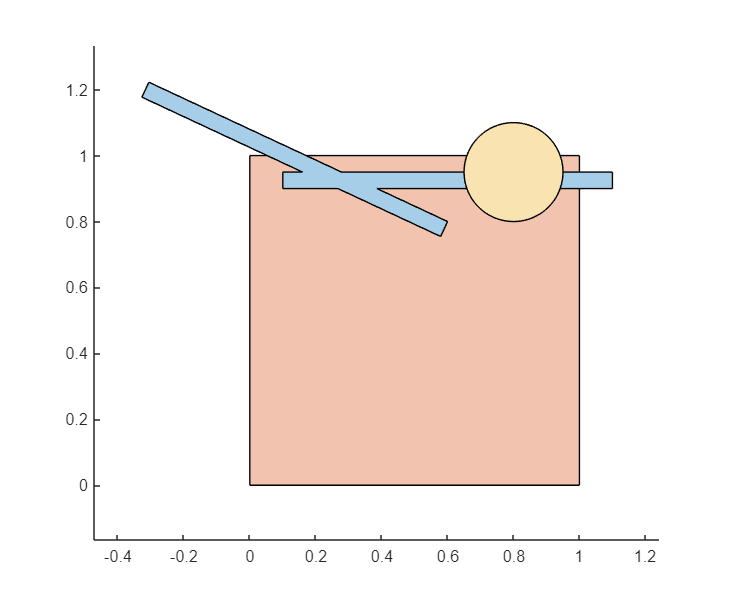

psBlock = subtract( psUnitSq, psRodAB );
psBlock = subtract( psBlock, psCircle );

psRodAB = subtract( psRodAB, psCircle );

psCell = { psRodAB; psBlock; psCircle };

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
boundsNew = addIntersectPnts( bounds, tol_intersect );

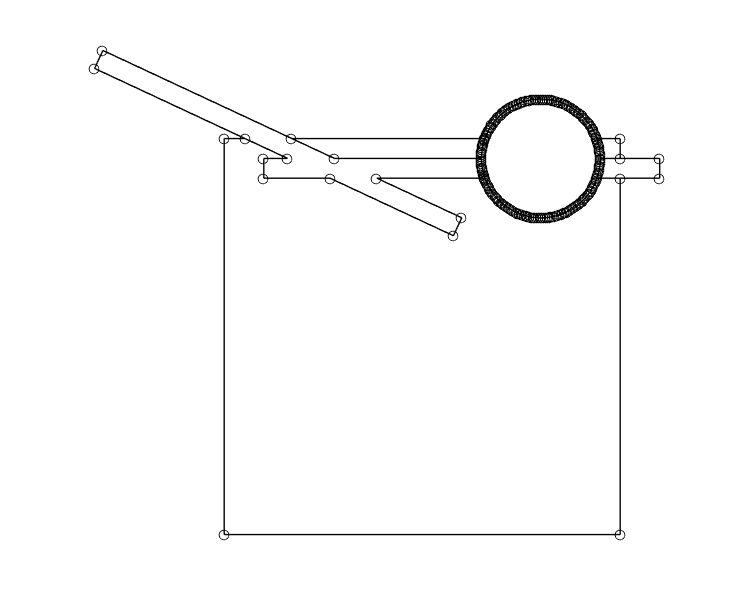

plotBounds(boundsNew,false,'ko-')

boundsCtrlP = getCtrlPnts( boundsNew, false );
boundsSimplified = simplifyBounds( boundsCtrlP, 0.001, 0 );

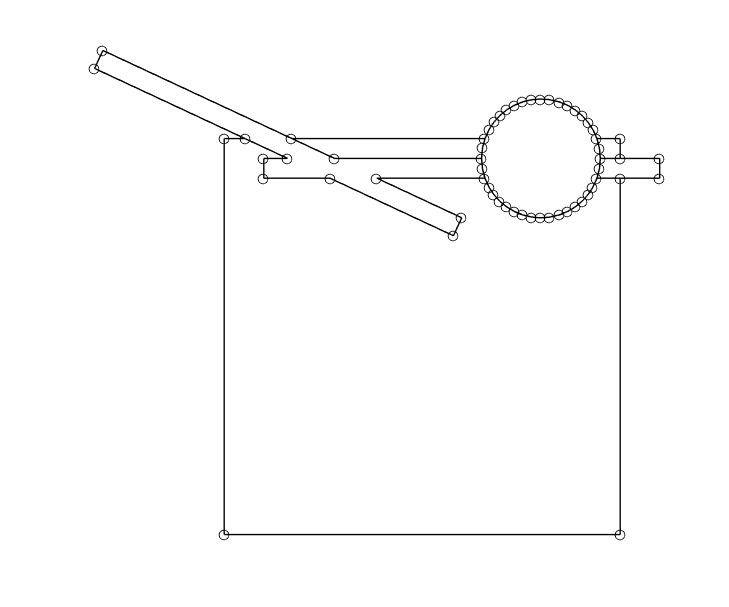

plotBounds(boundsSimplified,false,'ko-')

[ poly_node, poly_edge ] = getPolyNodeEdge( boundsSimplified );
[ vert,tria,tnum,vert2,tria2 ] = poly2mesh( poly_node, poly_edge, 500, 'delaunay', 0.25 );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                 97                 89
         10                101                189
         13                103                231


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                138                 89
         10                155                513
         16                161                686


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                155                682
          8                 15                682



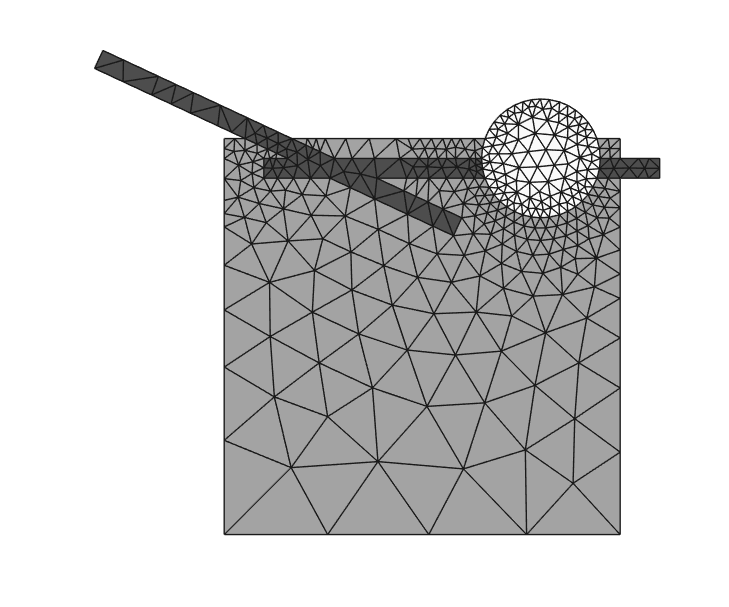

plotMeshes(vert,tria,tnum);